# Stochastic *Tribolium* Model Notes

## Preface

The goal here is to recode the original Markov chain formulation of the LPA *Tribolium* model, which was originally done in R, into MatLab. Here are the details of the model, copied from the R markdown file I was working on before R pissed me off enough to move back to MatLab.

## Introduction

One of the key questions motivating this project is, what proportion of the fluctuations observed in real population dynamics are driven by chaotic nonlinear interactions, and how much is due to (primarily demographic) stochasticity? And how do those contributions vary among the 3 dynamical phases characteristic of essentially all population dynamics: initial transient, transitional and asymptotic phases? 

Here's where we stand at the moment. The classic LPA model does not reproduce our data very well. We're in the process of trying to develop new models that explain our data better. We're having some success with deterministic discrete-time maps that extend the classical LPA formulation. As a contrast, here I build a model from purely stochastic considerations to compare to our deterministic approaches. This model is based on a Markov chain formulation with the following assumptions and notation:

- **Time:** The population is censused in time intervals of length $t_0$. Therefore, the model takes the form of a discrete-time stochastic process with time steps $\mathcal{T} = \{nt_0\}_{n=0}^N$. where $n$ identifies the (ordinated) census, and $N$ is the maximum number of censuses.

- **Dependent variables: **Like the classical LPA model, here I model the number of larvae, pupae and adults at each time step in $\mathcal{T}$. So I'll use the same notation: $L_n$, $P_n$ and $A_n$ are the number of larvae, pupae and adults at census $n$. However, unlike the LPA model, the dependent variables are discrete; here, $L_n$, $P_n$ and $A_n$ take values on the set of all non-negative integers.

- **Births: **The number of eggs laid by a single adult female in a single time step is Poisson-distributed with mean $2 \lambda$. All females are identical and lay eggs independently. The sex ratio is 1:1. Therefore, the total number of offspring born to the population in a single time step, $n$, is Poisson-distrubuted with mean $\sum_{i=1}^{A_n/2} 2 \lambda_i = 2 \frac{\lambda A_n}{2} = \lambda A_n$.

- **Natural mortality: **Every individual in a given class has an equal probability of dying; however, death rates among classes varies. The probability of death in a given time step for a given class is constant for all time. Let those probabilities be $\mu_l$, $\mu_p$ and $\mu_a$ for larvae, pupae and adults, respectively. Therefore, the numbers of individuals that die in all classes between arbitrary time steps $n$ and $n+1$ are binomially distributed with means $\mu_l L_n$, $\mu_p P_n$ and $\mu_a A_n$, for larvae, puapae and adults, respectively.

- **Cannibalism: **Adults eat eggs, small larvae and pupae, and large larvae eat eggs and small larvae. This assumption is equivalent to that in the classical LPA model. Consider adults cannibalizing eggs (and small larvae). Following the LPA model, I assume that the probability that an egg is eaten by an adult between time steps $n$ and $n + 1$ is $1 - e^{-c_{ea} A_n}$. The probability that the egg survives hatching and the first few instars is therefore $e^{-c_{ea} A_n}$. So the number of eggs/larvae that survive cannibalism is binomially distributed with this probability across $\lambda A_n$ trials. Similar considerations lead to the assumption that the number of eggs (and small larvae) that survive cannibalism by large larvae is binomially distributed with probability $e^{-c_{el} L_n}$, and the number of pupae that survive adult cannibalism is $e^{-c_{pa} A_n}$.

- **Time step structure: **A census occurs in a moment of time. Immediately after the census, adults lay eggs. After eggs are laid, cannibalism of larvae and pupae occurs, followed by natural mortality. Then all survivors advance 1 age class (eggs $\rightarrow$ larvae $\rightarrow$ pupae $\rightarrow$ adults) except adults, who remain adults until death.

## Model construction

Below I have a function that runs the model from a set of parameter values, maximum time horizon and initial conditions sent to it. It returns a data frame in the form of a MatLab table with variables "Census," "Time," "Larvae,", "Pupae," and "Adults." Default parameter values come from Table 1 of Dennis et al. (1995; Ecol. Monogr. 65:261). Values and range listed in the comments are taken directly from the composite maximum likelihood values and 95% confidence intervals listed in the last 2 columns of that table.

## Analysis

### Initial test

Since these are just the initial notes, I'll first test the function by sending it the default parameters to make sure it makes the correct calculation, or at least agrees with those of the analogous R script.

IC = [0,0,50];   % Initial conditions
MaxN = 20;       % Maximum time horizon

lambda = 11.68;  % Mean number of offspring per beetle (11.68; 6.2, 22.2)
muL    = 0.51;   % Probability of mortality for larvae (0.51; 0.43, 0.58)
muP    = 0;      % Probability of mortality for pupae (0; none listed in ref.)
muA    = 0.11;   % Probability of mortality for adults (0.11; 0.07, 0.15)

c_ea = 0.011;    % Rate at which adults eat eggs and small larvae (0.011, 0.004, 0.018)
c_el = 9.3e-3;   % Rate at which large larvae eat eggs and small larvae (0.0093, 0.0081, 0.0105)
c_pa = 0.018;    % Rate at which adults eat pupae (0.0178; 0.0154, 0.0207)

test = STMod(MaxN, IC, lambda, muL, muP, muA, c_ea, c_el, c_pa) % Run the model

test = 21×5 table
    Census    Time    Larvae    Pupae    Adults
    ______    ____    ______    _____    ______

       0        0        0         0       50  
       1        2      329         0       45  
       2        4       15       169       37  
       3        6      250         8      200  
       4        8       25       120      182  
       5       10      234        13      270  
       6       12       22       111      248  
       7       14      149        10      328  
       8       16       25        69      309  
       9       18       88        10      338  
      10       20       45        37      324  
      11       22       77        16      328  
      12       24       35        34      310  
      13       26       71        16      301  
      14       28       62        38      2

### Initial test plot

Now make the plot.

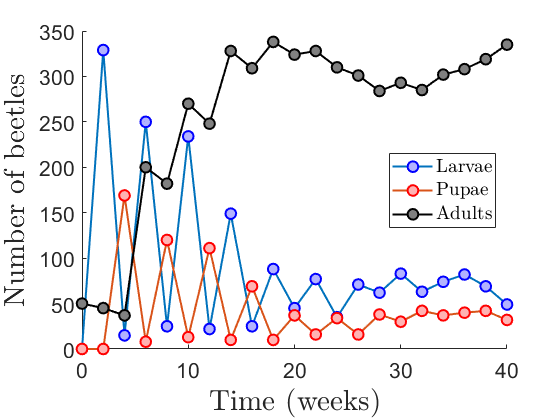

figure
hold on

plot(test.Time, test.Larvae, '-o', ...
    'MarkerSize', 8, ...
    'MarkerEdgeColor', 'b',...
    'MarkerFaceColor', [0.7 0.7 1], ...
    'LineWidth', 1.5)

plot(test.Time, test.Pupae, '-o', ...
    'MarkerSize', 8, ...
    'MarkerEdgeColor', 'r',...
    'MarkerFaceColor', [1 0.7 0.7], ...
    'LineWidth', 1.5)

plot(test.Time, test.Adults, '-o', ...
    'MarkerSize', 8, ...
    'MarkerEdgeColor', 'k',...
    'MarkerFaceColor', [0.5 0.5 0.5], ...
    'Color', 'k', ...
    'LineWidth', 1.5)

ax = gca;
ax.FontSize = 16;

xlabel('Time (weeks)', 'Interpreter', 'latex', 'FontSize', 22)
ylabel('Number of beetles', 'Interpreter', 'latex', 'FontSize', 22)
lgnd = legend('Larvae', 'Pupae', 'Adults');
lgnd.Interpreter = 'latex';
lgnd.Location = 'east';

OK, so that seems to be working. 

### Ensemble behavior

Here I'll plot multiple runs on a single plot to get a sense of the variation possible. Then I'll overlay the LPA solution with the same parameter values.

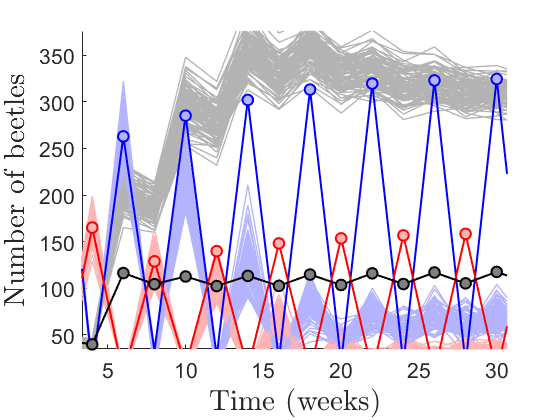

% STOCHASTIC MODEL:

nruns = 100;       % Number of times the model is run

figure

hold on

for i = 1:nruns

    % Run the model
    test = STMod(MaxN, IC, lambda, muL, muP, muA, c_ea, c_el, c_pa);

    % Plot the output before running again
    plot(test.Time, test.Larvae, ...
         'Color', [0.7 0.7, 1], ...
         'LineWidth', 1)

    plot(test.Time, test.Pupae, ...
         'Color', [1 0.7 0.7], ...
         'LineWidth', 1)

    plot(test.Time, test.Adults, ...
         'Color', [0.7 0.7 0.7], ...
         'LineWidth', 1)
end

% LPA MODEL:

LPASoln = LPAMod(MaxN, IC, lambda, muL, muA, c_ea, c_el, c_pa);

plot(LPASoln.Time, LPASoln.Larvae, '-o', ...
    'Color', 'b',...
    'MarkerSize', 8, ...
    'MarkerEdgeColor', 'b',...
    'MarkerFaceColor', [0.7 0.7 1], ...
    'LineWidth', 1.5)

plot(LPASoln.Time, LPASoln.Pupae, '-o', ...
    'Color', 'r',...
    'MarkerSize', 8, ...
    'MarkerEdgeColor', 'r',...
    'MarkerFaceColor', [[1 0.7 0.7]], ...
    'LineWidth', 1.5)

plot(LPASoln.Time, LPASoln.Adults, '-o', ...
    'Color', 'k',...
    'MarkerSize', 8, ...
    'MarkerEdgeColor', 'k',...
    'MarkerFaceColor', [0.5 0.5 0.5], ...
    'Color', 'k', ...
    'LineWidth', 1.5)

ax = gca;
ax.FontSize = 16;
legend
xlabel('Time (weeks)', 'Interpreter', 'latex', 'FontSize', 22)
ylabel('Number of beetles', 'Interpreter', 'latex', 'FontSize', 22)

Interestingly, the stochastic model shows oscillations largely driven by nonlinear interactions highlighted in the LPA model; however, the stochastic model does not match the analogous LPA model, except at first. This observation suggests that we should refine the stochastic model to better represent the LPA solution. Nevertheless, I find it interesting that both models settle into a period-2 orbit, just with different amplitudes.

## Stochastic model function

This function runs the stochastic Markov chain version of the LPA model.

**Parameters:  **`N `(max census); `ic` (initial conditions); `muL`, muP, `muA` (mortality probs for LPA); `c1`, `c2`, `c3` (cannibalism paramters).

**Returns: **`RunData: `A data frame with variables "census," "time," "L," "P," and "A."

function[RunData] = STMod(N, ic, lam, mu_L, mu_P, mu_A, c1, c2, c3)
    
    rng shuffle                  % Set seed for the random number generator to system clock

    census = 0:N;                        % Vector of census numbers, in chronological order
    time   = 2*census;                   % Vector of absolute times of each census, in weeks
    
    SMInit = zeros(N + 1, 3);            % Initialize the demographic data matrix
    SMInit(1,:) = ic;                    % Add initial conditions to demographic matrix
    
    % Main data table
    main = table(census', time', SMInit(:,1), SMInit(:,2), SMInit(:,3), ...
                 'VariableNames', ["Census", "Time", "Larvae", "Pupae", "Adults"]);
    
    for n = 1:N

      % Number of births
        eggs = poissrnd(lam*main.Adults(n));

      % Cannibalism
        eggs = binornd(eggs, exp(-c1*main.Adults(n)));           % Adult cannibalism on eggs
        eggs = binornd(eggs, exp(-c2*main.Larvae(n)));           % Larval cannibalism on eggs
        pupae = binornd(main.Pupae(n), exp(-c3*main.Adults(n))); % Adult cannibalism on pupae

     % Natural mortality and age-class advancement
        main.Larvae(n+1) = eggs;                                 % Surviving eggs become larvae
        main.Pupae(n+1)  = binornd(main.Larvae(n), 1-mu_L);      % Surviving larvae become pupae
        main.Adults(n+1) = binornd(main.Adults(n), 1-mu_A) +...
                           binornd(main.Pupae(n), 1-mu_P);       % Surviving adults + pupae

    end

    RunData = main;

end

## LPA model function

This function runs the classical LPA model. It takes the same inputs (except for pupal mortality) and returns a similar data structure as does the stochastic model function.

function[LPAData] = LPAMod(N, ic, lam, mu_L, mu_A, c1, c2, c3)

    census = 0:N;                        % Vector of census numbers, in chronological order
    time   = 2*census;                   % Vector of absolute times of each census, in weeks
    
    LPAInit = zeros(N + 1, 3);           % Initialize the demographic data matrix
    LPAInit(1,:) = ic;                   % Add initial conditions to demographic matrix
    
    % Main data table
    main = table(census', time', LPAInit(:,1), LPAInit(:,2), LPAInit(:,3), ...
                 'VariableNames', ["Census", "Time", "Larvae", "Pupae", "Adults"]);
    
    for n = 1:N

        xNow = [main.Larvae(n) main.Pupae(n) main.Adults(n)]';  % x_n vector of [L P A]_n
        
        % Projection matrix
        P = [0, 0, lam*exp(-c1*main.Adults(n) - c2*main.Larvae(n));
             1 - mu_L, 0, 0;
             0, exp(-c3*main.Adults(n)), 1 - mu_A];
        
        % Compute the next census
        main{n+1, ["Larvae", "Pupae", "Adults"]} = (P*xNow)';
    end

    LPAData = main;
end
